%"Dispatcher" by Kambadur Ananthamurthy
% This code uses actual dfbf curves from my data and analyses it for time
% cells using multiple methods
% Currently this is being tested for single session data. I will test with a
% batch, soon.

tic
clear
close all

## Addpaths


addpath(genpath('/Users/ananth/Documents/MATLAB/CustomFunctions')) % my custom functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis')) % Additional functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis/Suite2P-ananth'))
addpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis/Suite2P-ananth/localCopies')


## Dataset details

make_db
ops0.fig                       = 1;
ops0.saveData                  = 1;
ops0.onlyProbeTrials           = 0;
ops0.loadSyntheticData         = 1;
ops0.doSigOnly                 = 0;
ops0.consolidate               = 1;

if ops0.consolidate
    cDate                      = 20210621;
    cRun                       = 1;
end
% Methods - 0: Don't run; 1: Run
runMethodA  = 1; 
runMethodB  = 1;
runMethodC  = 1;
runMethodD  = 1;
runMethodE  = 1;
runMethodF  = 1;

if ops0.loadSyntheticData
    setupSyntheticDataParametersSingle
end

## Figure details

if ops0.fig
    figureDetails = compileFigureDetails(20, 2, 10, 0.5, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
end

## Main script

fprintf('Analyzing %s_%i_%i - Date: %s\n', db.mouseName, ...
    db.sessionType, ...
    db.session, ...
    db.date)

Analyzing M26_5_4 - Date: 20180514


saveDirec = '/Users/ananth/Desktop/Work/Analysis/Imaging/';
saveFolder = [saveDirec db.mouseName '/' db.date '/'];
if ops0.loadSyntheticData
    i = length(sdcp);
    load([saveFolder ...
        'synthDATA' ...
        '_tCP' num2str(sdcp(i).timeCellPercent) ...
        '_cO' lower(sdcp(i).cellOrder) ...
        '_mHTP' num2str(sdcp(i).maxHitTrialPercent) ...
        '_hTPA' lower(sdcp(i).hitTrialPercentAssignment) ...
        '_tO' lower(sdcp(i).trialOrder) ...
        '_eW' num2str(sdcp(i).eventWidth{1}) ...
        '_eAF' num2str(sdcp(i).eventAmplificationFactor) ...
        '_eT' lower(sdcp(i).eventTiming) ...
        '_sF' num2str(sdcp(i).startFrame) ...
        '_eF' num2str(sdcp(i).endFrame) ...
        '_iFWHM' num2str(sdcp(i).imprecisionFWHM) ...
        '_iT' lower(sdcp(i).imprecisionType) ...
        '_n' lower(sdcp(i).noise) ...
        '_np' num2str(sdcp(i).noisePercent) ...
        '.mat']);
    myData.dfbf = sdo.syntheticDATA;
    myData.dfbf_2D = sdo.syntheticDATA_2D;
    myData.baselines = zeros(size(sdo.syntheticDATA)); %initialization
else
    %Load processed data (processed dfbf for dataset/session)
    myData = load([saveFolder db.mouseName '_' db.date '.mat']);
end

%d2d = reshape(myData.dfbf, 2, []);
%mustBeNonnegative(d2d)

%mustBeNonnegative(myData.dfbf_2D)

trialDetails = getTrialDetails(db);
%Significant-Only Traces
if ops0.doSigOnly
    if ops0.onlyProbeTrials
        disp('Only analysing Probe Trials ...')
        dfbf_sigOnly = findSigOnly(myData.dfbf(:, iProbeTrials, :));
    else
        dfbf_sigOnly = findSigOnly(myData.dfbf);
    end
    DATA = dfbf_sigOnly;
else
    DATA = myData.dfbf;
end

## Analysis Pipeline: Method A - Mehrab's Reliability Analysis (Bhalla Lab)

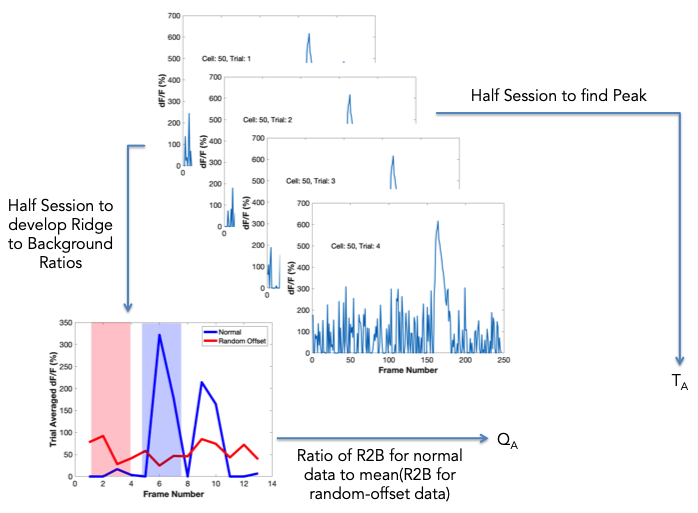

Now calculating Ridge to Background Ratios ...
... 50 cells examined ...
... 100 cells examined ...


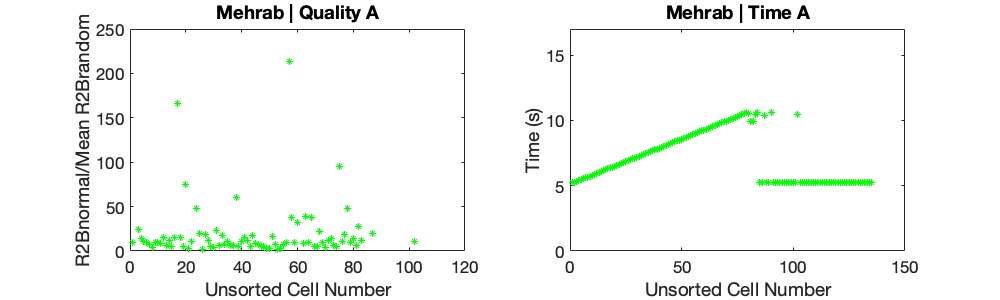

if runMethodA
    %Method A - Mehrab's Reliability Analysis (Bhalla Lab)
    mAInput.cellList = 1:1:size(DATA,1); %using all cells
    mAInput.onFrame = 75;
    mAInput.offFrame = 150;
    mAInput.ridgeHalfWidth = 100; %in ms
    mAInput.nIterations = 1; %number of iterations of randomisation used to find averaged r-shifted rb ratio - might have to go as high as 3000.
    mAInput.selectNonOverlappingTrials = 1; %1 - non-overlapping trial sets usenIterations = 1 for kernel estimation and rb ratio calculation, 0 - all trials used for both
    mAInput.earlyOnly = 0; %0 - uses all trials; 1 - uses only the first 5 trials of the session
    mAInput.startTrial = 1; %the analysis begins with this trial number (e.g. - 1: analysis on all trials)
    [mAOutput] = runMehrabR2BAnalysis(DATA, mAInput, trialDetails);
    mAOutput.normQ = (mAOutput.Q)/max(mAOutput.Q(~isinf(mAOutput.Q)));
    
    save([saveFolder db.mouseName '_' db.date '_methodA.mat' ], 'mAInput', 'mAOutput')

    fig1 = figure(1);
    set(fig1,'Position',[300, 300, 1000, 300])
    clf
    subplot(1, 2, 1)
    plot(mAOutput.Q, 'g*')
    title('Mehrab | Quality A', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('R2Bnormal/Mean R2Brandom', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(1, 2, 2)
    plot(mAOutput.T/db.samplingRate, 'g*')
    ylim([0 (db.nFrames/db.samplingRate)])
    %ylim([(mAInput.onFrame-10)/db.samplingRate (mAInput.offFrame + 10)/db.samplingRate])
    title('Mehrab | Time A', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Time (s)', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    if ops0.loadSyntheticData
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodA_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
            '-djpeg');
    else
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodA_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
            '-djpeg');
    end
end

## Analysis Pipeline: Method B - William Mau's Temporal Information (Eichenbaum Lab)

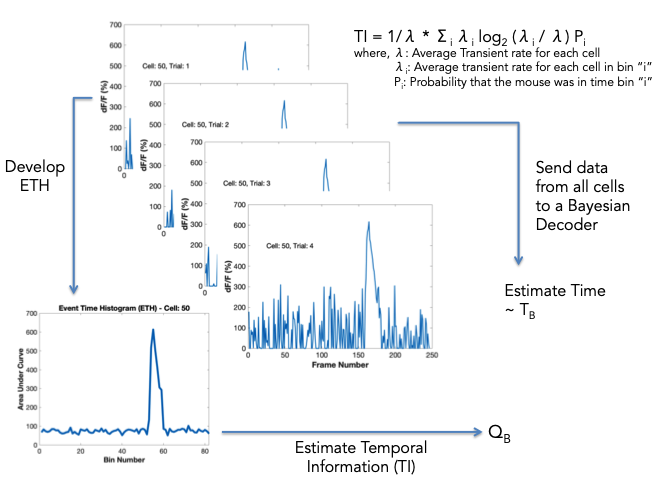

>>> Randomized dataset: 1 of 1 ...
Label Shuffle Control: off


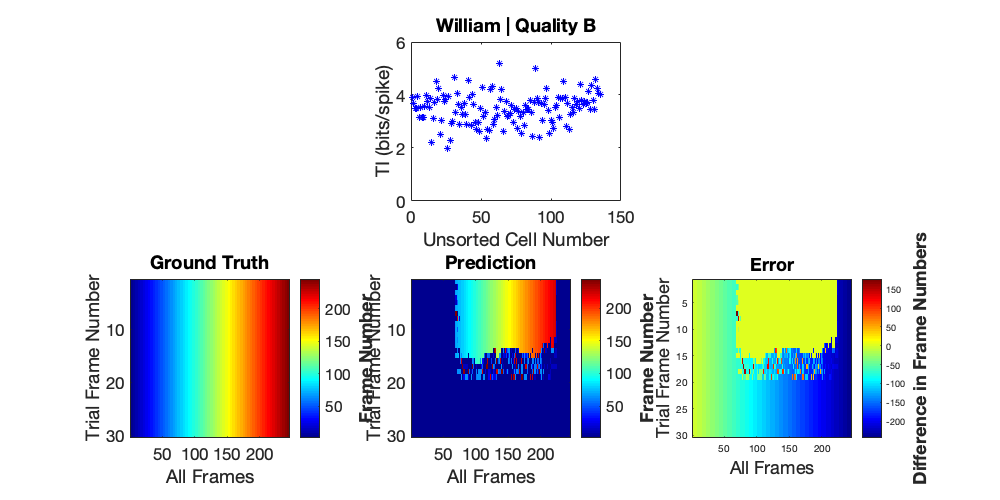

if runMethodB
    %Method B - William Mau's Temporal Information (Eichenbaum Lab)
    mBInput.delta = 3;
    mBInput.whichTrials = 'alternate';
    mBInput.labelShuffle = 'off';
    mBInput.distribution4Bayes = 'mvmn';
    mBInput.saveModel = 0;
    %mBInput.nIterations = 1000;
    mBInput.nIterations = 1;
    mBInput.startFrame = 75;
    mBInput.endFrame = 130;
    mBInput.threshold = 99; %in %
    if ~mBInput.saveModel
        try
            mBOutput = rmfield(mBOutput, 'Mdl');
        catch
        end
    end
    
    [mBOutput] = runWilliamTIAnalysis(DATA, mBInput);
    mBOutput.normQ = (mBOutput.Q)/max(mBOutput.Q);
    
    save([saveFolder db.mouseName '_' db.date '_methodB.mat' ], 'mBInput', 'mBOutput')
    
    fig2 = figure(2);
    set(fig2,'Position',[300, 300, 1000, 500])
    clf
    subplot(2, 3, 2)
    plot(mBOutput.Q, 'b*')
    title('William | Quality B' , ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('TI (bits/spike)', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(2, 3, 4)
    imagesc(mBOutput.Yfit_actual_2D)
    colormap('jet')
    z = colorbar;
    ylabel(z,'Frame Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    title('Ground Truth', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    xlabel('All Frames', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    ylabel('Trial Frame Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(2, 3, 5)
    imagesc(mBOutput.Yfit_2D)
    z = colorbar;
    ylabel(z,'Frame Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    title('Prediction', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    xlabel('All Frames', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    ylabel('Trial Frame Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(2, 3, 6)
    imagesc(mBOutput.YfitDiff_2D)
    z = colorbar;
    ylabel(z,'Difference in Frame Numbers', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    title('Error', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    xlabel('All Frames', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    ylabel('Trial Frame Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    
    if ops0.loadSyntheticData
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodB_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
            '-djpeg');
    else
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodB_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
            '-djpeg');
    end
end

## Analysis Pipeline: Method C - Simple Analysis

Method C1

Now, developing ETH for 135 cells ...
... 50 cells analysed ...
... 100 cells analysed ...
... done!
>>> Randomized dataset: 1 of 1 ...
Now, developing ETH for 135 cells ...
... 50 cells analysed ...
... 100 cells analysed ...
... done!


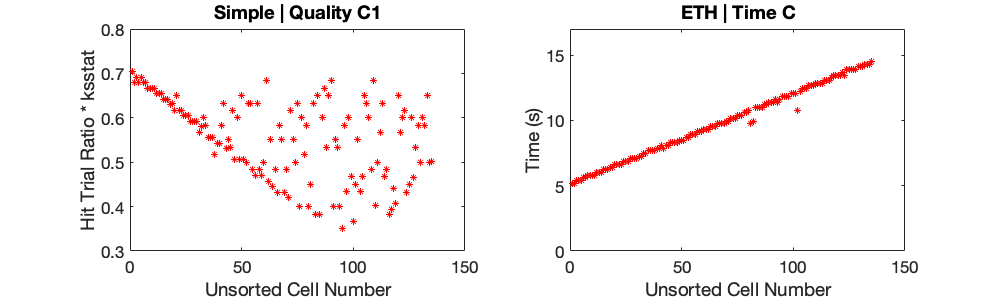

if runMethodC
    %Method C - Simple Analysis
    mCInput.delta = 3;
    mCInput.skipFrames = [];
    mCInput.trialThreshold = 25; % in %
    %mCInput.nIterations = 1000;
    mCInput.nIterations = 1;
    mCInput.startFrame = 75;
    mCInput.endFrame = 130;
    mCInput.threshold = 99; %in %
    [mCOutput] = runSimpleTCAnalysis(DATA, mCInput);
    mCOutput.normQ1 = (mCOutput.Q1)/max(mCOutput.Q1);
    mCOutput.normQ2 = (mCOutput.Q2)/max(mCOutput.Q2);
    
    save([saveFolder db.mouseName '_' db.date '_methodC.mat' ], 'mCInput', 'mCOutput')
    
    fig3 = figure(3);
    set(fig3,'Position',[300, 300, 1000, 300])
    clf
    subplot(1, 2, 1)
    plot(mCOutput.Q1, 'r*')
    title('Simple | Quality C1' , ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Hit Trial Ratio * ksstat', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(1, 2, 2)
    plot((mCOutput.T * mCInput.delta)/db.samplingRate, 'r*')
    ylim([0 (db.nFrames/db.samplingRate)])
    title('ETH | Time C', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Time (s)', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    if ops0.loadSyntheticData
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC1_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
            '-djpeg');
    else
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC1_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
            '-djpeg');
    end
end

Method C2

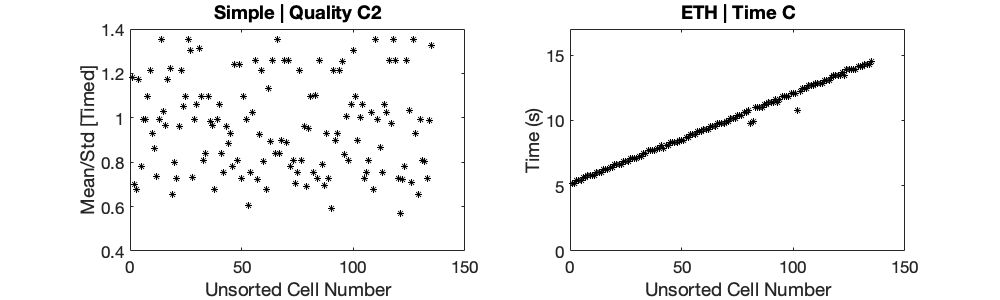

if runMethodC
    fig4 = figure(4);
    set(fig4,'Position',[300, 300, 1000, 300])
    clf
    subplot(1, 2, 1)
    plot(mCOutput.Q2, 'k*')
    %ylim([0 10])
    title('Simple | Quality C2' , ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Mean/Std [Timed]', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(1, 2, 2)
    plot((mCOutput.T * mCInput.delta)/db.samplingRate, 'k*')
    ylim([0 (db.nFrames/db.samplingRate)])
    title('ETH | Time C', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Time (s)', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    if ops0.loadSyntheticData
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC2_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
            '-djpeg');
    else
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC2_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
            '-djpeg');
    end
end

## Analysis Pipeline: Method D - Sequence based analysis

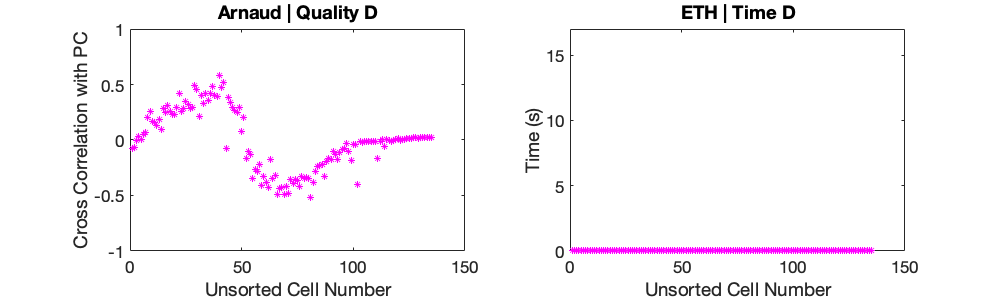

if runMethodD
    %Method D - Arnaud Malvache' PCA based Analysis for Sequences
    mDInput.delta = 3;
    mDInput.skipFrames = [];
    mDInput.gaussianSmoothing = 1; %logical
    mDInput.nSamples = 5; %for Gaussian Kernel; relevant only if gaussian smoothing is on
    mDInput.automatic = 1; %for selecting P; logical
    mDInput.timeVector = (1:db.nFrames*size(DATA,2)) * (1/db.samplingRate); %in seconds; %For derivative
    mDInput.getT = 0;
    [mDOutput] = runSeqBasedTCAnalysis(DATA, mDInput);
    mDOutput.normQ = (mDOutput.Q) ./max(mDOutput.Q);
    
    save([saveFolder db.mouseName '_' db.date '_methodD.mat' ], 'mDInput', 'mDOutput')
   
    fig5 = figure(5);
    set(fig5,'Position',[300, 300, 1000, 300])
    clf
    subplot(1, 2, 1)
    plot(mDOutput.Q, 'm*')
    title('Arnaud | Quality D' , ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Cross Correlation with PC', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(1, 2, 2)
    plot((mDOutput.T * mDInput.delta)/db.samplingRate, 'm*')
    ylim([0 (db.nFrames/db.samplingRate)])
    title('ETH | Time D', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Time (s)', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
end

## Analysis Pipeline E - Support Vector Machine based Classification

Label Shuffle Control: off
**** Caught a dataset with only 1 column ****


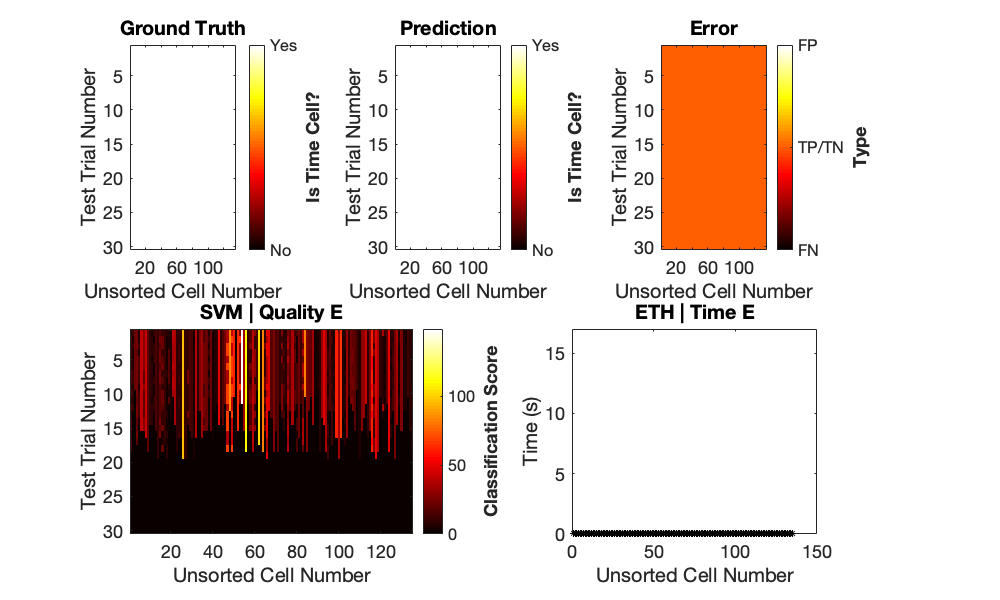

if runMethodE
    %Method E - SVM based classification of cells
    mEInput.delta = 3;
    mEInput.skipFrames = [];
    mEInput.gaussianSmoothing = 0; %logical
    mEInput.nSamples = 5; %for Gaussian Kernel; relevant only if gaussian smoothing is on
    mEInput.whichTrials = 'alternate';
    mEInput.labelShuffle = 'off';
    mEInput.getT = 0;
    if ops0.loadSyntheticData
        mEInput.ptcList = sdo.ptcList;
        mEInput.ocList = sdo.ocList;
    else
        if strcmpi(mEInput.whichCells, 'timeCells')
            mEInput.ptcList = input('Enter Time Cell List: ');
        elseif strcmpi(mEInput.whichCells, 'otherCells')
            mEInput.ocList = input('Enter Other Cell List: ');
        end
    end
    
    mEInput.saveModel = 0;
    if ~mEInput.saveModel
        try
            mEOutput = rmfield(mEOutput, 'SVMModel');
        catch
        end
    end
    [mEOutput] = runSVMClassification(DATA, mEInput);
    mEOutput.normQ = (mEOutput.Q) ./max(mEOutput.Q);
    
    save([saveFolder db.mouseName '_' db.date '_methodE.mat' ], 'mEInput', 'mEOutput')

    fig6 = figure(6);
    set(fig6,'Position',[300, 300, 1000, 600])
    clf
    subplot(2, 9, 1:2)
    imagesc(mEOutput.Yfit_actual_2D)
    colormap('hot')
    z = colorbar('XTickLabel',{'No', 'Yes'}, ...
               'XTick', 0:1:1);
    ylabel(z,'Is Time Cell?', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    caxis([0 1])
    title('Ground Truth', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    ylabel('Test Trial Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-2)
    
    subplot(2, 9, 4:5)
    imagesc(mEOutput.Yfit_2D)
    z = colorbar('XTickLabel',{'No', 'Yes'}, ...
               'XTick', 0:1:1);
    ylabel(z,'Is Time Cell?', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    caxis([0 1])
    title('Prediction', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    ylabel('Test Trial Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-2)
    
    subplot(2, 9, 7:8)
    imagesc(mEOutput.YfitDiff_2D)
    z = colorbar('XTickLabel',{'FN', 'TP/TN', 'FP'}, ...
               'XTick', -1:1:1);
    ylabel(z,'Type', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    caxis([-1 1])
    title('Error', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    ylabel('Test Trial Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-2)
    
    subplot(2, 9, 10:13)
    imagesc(mEOutput.Q_2D)
    z = colorbar;
    ylabel(z,'Classification Score', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    caxis([min(min(mEOutput.Q_2D)), max(max(mEOutput.Q_2D))])
    title('SVM | Quality E' , ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Test Trial Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-2)
    
    subplot(2, 9, 15:17)
    plot((mEOutput.T * mEInput.delta)/db.samplingRate, 'k*')
    ylim([0 (db.nFrames/db.samplingRate)])
    title('ETH | Time E', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Time (s)', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-2)
    
    if ops0.loadSyntheticData
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodE_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
            '-djpeg');
    else
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodE_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
            '-djpeg');
    end
end

## Analysis Pipeline F - Derived Parametric Equations

Method F1

Now, developing ETH for 135 cells ...
... 50 cells analysed ...
... 100 cells analysed ...
... done!
>>> Randomized dataset: 1 of 1 ...
Now, developing ETH for 135 cells ...
... 50 cells analysed ...
... 100 cells analysed ...
... done!


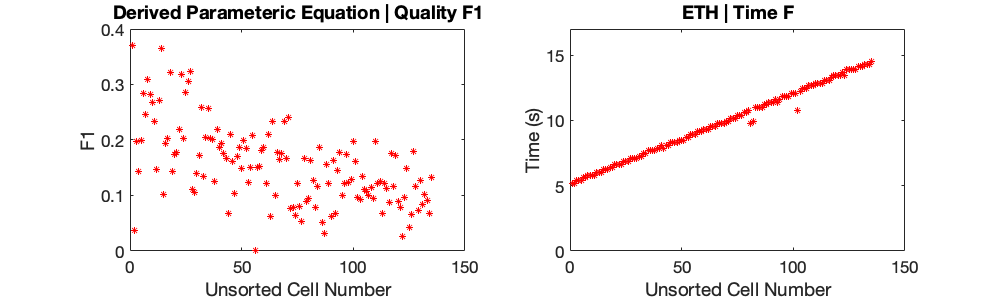

if runMethodF
    %Method F - Parametric Equation
    %%%ADD DB as INPUT.
    mFInput.delta = 3;
    mFInput.skipFrames = [];
    mFInput.alpha = 10;
    mFInput.beta = 1;
    mFInput.gamma = 10;
    %mFInput.nIterations = 1000;
    mFInput.nIterations = 1;
    mFInput.startFrame = 75;
    mFInput.endFrame = 130;
    mFInput.threshold = 99; %in %
    mFInput.db = db;
    mFInput.saveFolder = saveFolder;
    [mFOutput] = runDerivedQAnalysis(DATA, mFInput);
    mFOutput.normQ1 = (mFOutput.Q1)/max(mFOutput.Q1);
    mFOutput.normQ2 = (mFOutput.Q2)/max(mFOutput.Q2);
        
    save([saveFolder db.mouseName '_' db.date '_methodF.mat' ], 'mFInput', 'mFOutput')
    
    fig7 = figure(7);
    set(fig7,'Position',[300, 300, 1000, 300])
    clf
    subplot(1, 2, 1)
    plot(mFOutput.Q1, 'r*')
    title('Derived Parameteric Equation | Quality F1' , ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('F1', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(1, 2, 2)
    plot((mFOutput.T * mCInput.delta)/db.samplingRate, 'r*')
    ylim([0 (db.nFrames/db.samplingRate)])
    title('ETH | Time F', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Time (s)', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    if ops0.loadSyntheticData
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodF1_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
            '-djpeg');
    else
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodF1_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
            '-djpeg');
    end
end

Method F2

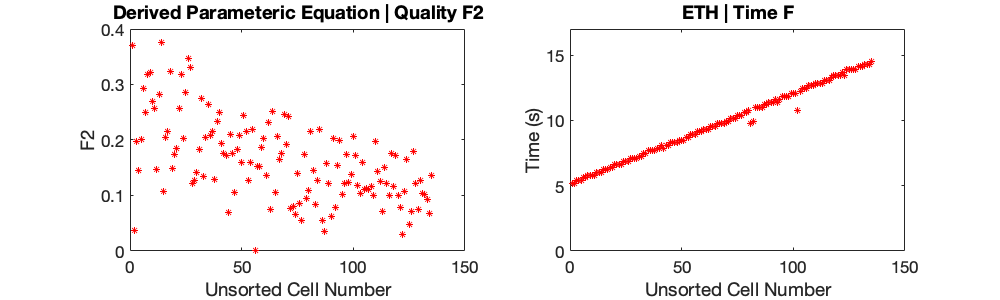

if runMethodF
    fig8 = figure(8);
    set(fig8,'Position',[300, 300, 1000, 300])
    clf
    subplot(1, 2, 1)
    plot(mFOutput.Q2, 'r*')
    title('Derived Parameteric Equation | Quality F2' , ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('F2', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(1, 2, 2)
    plot((mFOutput.T * mCInput.delta)/db.samplingRate, 'r*')
    ylim([0 (db.nFrames/db.samplingRate)])
    title('ETH | Time F', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Time (s)', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    if ops0.loadSyntheticData
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodF2_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
            '-djpeg');
    else
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodF2_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
            '-djpeg');
    end
end

## Second Order Stats to compare the outputs

## For single session

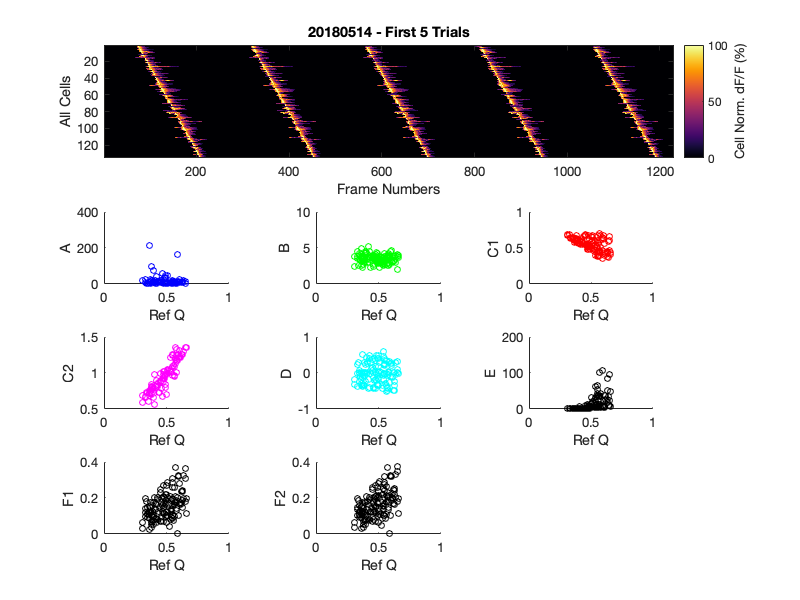

mouseName = 'M26';
recordingDate = 20180514; %imaging session
cDate = 20210324; %consolidation date
cRun = 1; %consolidation run number

plotRefQ = 1;
plotAnalysedQs = 1;
plotDatasetCheck = 0;

dfbf_2D = sdo.syntheticDATA_2D;

normalizeScatterPlots = 0;  %for scatter plots
normalizeDataVisual = 1; % 0: global normalization; 1: cell-wise normalization

if normalizeDataVisual
    norm_dfbf_2D = zeros(size(dfbf_2D));
    for cell = 1:size(dfbf_2D)
        cellMax = max(dfbf_2D(cell, :));
        norm_dfbf_2D(cell, :) = dfbf_2D(cell, :)/cellMax;
    end
end

figureDetails = compileFigureDetails(13, 2, 10, 0.5, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
%Extra colormap options: inferno/plasma/viridis/magma

nCells = 135;
nFrames = 246;
nTrials = 5;
nMethods = 8;

fig1 = figure(1);
clf
set(fig1,'Position',[0, 200, 800, 600])
subplot(12, 9, 1:27) %Data visual
if normalizeDataVisual
    imagesc(norm_dfbf_2D(:, 1:nTrials*nFrames)*100);
else
    imagesc(dfbf_2D(:, 1:nTrials*nFrames)*100);
end
colormap(figureDetails.colorMap)
title(sprintf('%i - First 5 Trials', recordingDate), ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
xlabel('Frame Numbers', ...
    'FontSize', figureDetails.fontSize)
ylabel('All Cells', ...
    'FontSize', figureDetails.fontSize)
z = colorbar;
if normalizeDataVisual
    ylabel(z,'Cell Norm. dF/F (%)', ...
        'FontSize', figureDetails.fontSize)
else
    ylabel(z,'dF/F (%)', ...
        'FontSize', figureDetails.fontSize)
end
set(gca,'FontSize', figureDetails.fontSize)

%Scatter plots
%C = distinguishable_colors(6);
if normalizeScatterPlots == 1
    for count = 1:nMethods
        x = sdo.Q;
        if count == 1
            subplot(12, 9, [37:38, 46:47])
            y = mAOutput.normQ;
            scatter(x, y, 'b');
            ylabel('A', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 2
            subplot(12, 9, [40:41, 49:50])
            y = mBOutput.normQ;
            scatter(x, y, 'g');
            ylabel('B', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 3
            subplot(12, 9, [43:44, 52:53])
            y = mCOutput.normQ1;
            scatter(x, y, 'r');
            ylabel('C1', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 4
            subplot(12, 9, [64:65, 73:74])
            y = mCOutput.normQ2;
            scatter(x, y, 'm');
            ylabel('C2', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 5
            subplot(12, 9, [67:68, 76:77])
            y = mDOutput.normQ;
            scatter(x, y, 'c');
            ylabel('D', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 6
            subplot(12, 9, [70:71, 79:80])
            y = mEOutput.normQ;
            scatter(x, y, 'k');
            ylabel('E', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 7
            subplot(12, 9, [91:92, 100:101])
            y = mFOutput.normQ1;
            scatter(x, y, 'k');
            ylabel('F1', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 8
            subplot(12, 9, [94:95, 103:104])
            y = mFOutput.normQ2;
            scatter(x, y, 'k');
            ylabel('F2', ...
                'FontSize', figureDetails.fontSize)
        else
            str = {'Will add dataset','details here'};
            text(2,7,str)
        end
        xlabel('Ref Q', ...
            'FontSize', figureDetails.fontSize)
        xlim([0, 1])
        set(gca,'FontSize', figureDetails.fontSize)
    end
else %No normalization
    for count = 1:nMethods
        x = sdo.Q;
        if count == 1
            subplot(12, 9, [37:38, 46:47])
            y = mAOutput.Q;
            scatter(x, y, 'b');
            ylabel('A', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 2
            subplot(12, 9, [40:41, 49:50])
            y = mBOutput.Q;
            scatter(x, y, 'g');
            ylabel('B', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 3
            subplot(12, 9, [43:44, 52:53])
            y = mCOutput.Q1;
            scatter(x, y, 'r');
            ylabel('C1', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 4
            subplot(12, 9, [64:65, 73:74])
            y = mCOutput.Q2;
            scatter(x, y, 'm');
            ylabel('C2', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 5
            subplot(12, 9, [67:68, 76:77])
            y = mDOutput.Q;
            scatter(x, y, 'c');
            ylabel('D', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 6
            subplot(12, 9, [70:71, 79:80])
            y = mEOutput.Q;
            scatter(x, y, 'k');
            ylabel('E', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 7
            subplot(12, 9, [91:92, 100:101])
            y = mFOutput.Q1;
            scatter(x, y, 'k');
            ylabel('F1', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 8
            subplot(12, 9, [94:95, 103:104])
            y = mFOutput.Q2;
            scatter(x, y, 'k');
            ylabel('F2', ...
                'FontSize', figureDetails.fontSize)
        else
        end
        xlabel('Ref Q', ...
            'FontSize', figureDetails.fontSize)
        xlim([0, 1])
        set(gca,'FontSize', figureDetails.fontSize)
    end
end
clear x
clear y
print(['/Users/ananth/Desktop/' ...
    'Figure4i_realData_' ...
    mouseName '_' num2str(recordingDate)], ...
    '-djpeg')

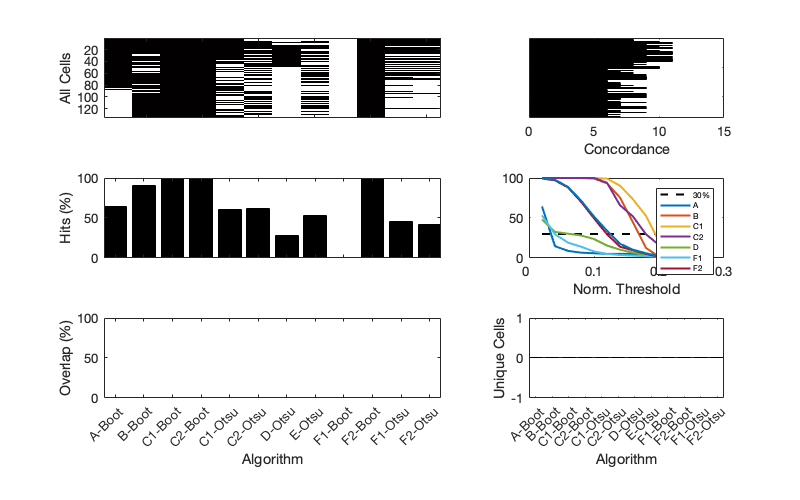


%% Classification
nAlgos = 12;
iddTimeCells = zeros(nCells, nAlgos);
allScores = zeros(nCells, nMethods);

%(fontSize, lineWidth, markerSize, transparency, colorMap)
figureDetails = compileFigureDetails(13, 2, 5, 0, 'hot'); %inferno/plasma/viridis/magma

for algo = 1:nAlgos
    if algo == 1
        iddTimeCells(:, algo) = squeeze(mAOutput.timeCells);
    elseif algo == 2
        iddTimeCells(:, algo) = squeeze(mBOutput.timeCells);
    elseif algo == 3
        iddTimeCells(:, algo) = squeeze(mCOutput.timeCells1);
    elseif algo == 4
        iddTimeCells(:, algo) = squeeze(mCOutput.timeCells2);
    elseif algo == 5
        iddTimeCells(:, algo) = squeeze(mCOutput.timeCells3);
    elseif algo == 6
        iddTimeCells(:, algo) = squeeze(mCOutput.timeCells4);
    elseif algo == 7
        iddTimeCells(:, algo) = squeeze(mDOutput.timeCells);
    elseif algo == 8
        iddTimeCells(:, algo) = squeeze(mEOutput.timeCells);
    elseif algo == 9
        iddTimeCells(:, algo) = squeeze(mFOutput.timeCells1);
    elseif algo == 10
        iddTimeCells(:, algo) = squeeze(mFOutput.timeCells2);
    elseif algo == 11
        iddTimeCells(:, algo) = squeeze(mFOutput.timeCells3);
    elseif algo == 12
        iddTimeCells(:, algo) = squeeze(mFOutput.timeCells4);
    end
end

fig2 = figure(2);
clf
set(fig2,'Position',[800, 200, 800, 500])
subplot(9, 9, [1:5, 10:14])
imagesc(iddTimeCells)
%colormap(figureDetails.colorMap)
colormap(gca, flipud(figureDetails.colorMap))
%colormap(flipud(hot))
%caxis([0 1.1])
%title(sprintf('Classification | Real Data - %i', date))
xticklabels({})
% xlabel('Algorithm', ...
%     'FontSize', figureDetails.fontSize-5, ...
%     'FontWeight', 'bold')
% xticklabels({'Ar', 'Br', 'C1r', 'C2r', 'C1o', 'C2o', 'Do', 'F1r', 'F2r', 'F1o', 'F2o'})
% xtickangle(45)
ylabel('All Cells', ...
    'FontSize', figureDetails.fontSize)
set(gca, 'FontSize', figureDetails.fontSize)

methodHits = zeros(nCells, 1);
for cell = 1:nCells
    methodHits(cell, 1) = numel(find(iddTimeCells(cell, :)));
end
subplot(9, 9, [7:9, 16:18])
%imagesc(methodHits*100/nAlgos)
barh(methodHits, 'black')
set(gca, 'YDir','reverse')
%title('Concordance')
%xticklabels({})
xlabel('Concordance', ...
    'FontSize', figureDetails.fontSize)
yticklabels({})
set(gca, 'FontSize', figureDetails.fontSize)

percentHits = nansum(iddTimeCells, 1)*100/nCells;
subplot(9, 9, [28:32, 37:41])
%plot(percentHits, 'bo', 'MarkerSize', 10)
bar(percentHits, 'black')
axis tight
xticklabels({})
% xlabel('Algorithm', ...
%     'FontSize', figureDetails.fontSize-5, ...
%     'FontWeight', 'bold')
% xticklabels({'Ar', 'Br', 'C1r', 'C2r', 'C1o', 'C2o', 'Do', 'F1r', 'F2r', 'F1o', 'F2o'})
% xtickangle(45)
ylim([0 100])
ylabel('Hits (%)', ...
    'FontSize', figureDetails.fontSize)
set(gca, 'FontSize', figureDetails.fontSize)

for method = 1:nMethods
    if method == 1
        allScores(:, method) = squeeze(mAOutput.normQ);
    elseif method == 2
        allScores(:, method) = squeeze(mBOutput.normQ);
    elseif method == 3
        allScores(:, method) = squeeze(mCOutput.normQ1);
    elseif method == 4
        allScores(:, method) = squeeze(mCOutput.normQ2);
    elseif method == 5
        allScores(:, method) = squeeze(mDOutput.normQ);
    elseif method == 6
        allScores(:, method) = squeeze(mEOutput.normQ);
    elseif method == 7
        allScores(:, method) = squeeze(mFOutput.normQ1);
    elseif method == 8
        allScores(:, method) = squeeze(mFOutput.normQ2);
    end
end
estimatedPercentHits = zeros(numel(0:0.1:1), nMethods);
count = 0;
for thresh = 0:0.1:1
    count = count+1;
    for method = 1:nMethods
        estimatedPercentHits(count, method) = (numel(find(allScores(:, method)>thresh))*100)/nCells;
    end
end
subplot(9, 9, [34:36, 43:45])
thirtyPercentLine = 30*(ones(11, 1));
plot(thirtyPercentLine, '--k', 'LineWidth', figureDetails.lineWidth, 'MarkerSize', figureDetails.markerSize)
hold on
plot(estimatedPercentHits, 'LineWidth', figureDetails.lineWidth, 'MarkerSize', figureDetails.markerSize)
hold off
% title('Classification vs Threshold')
xticklabels({0:0.1:1})
xlabel('Norm. Threshold', ...
    'FontSize', figureDetails.fontSize)
set(gca, 'FontSize', figureDetails.fontSize)
lgd = legend('30%', 'A', 'B', 'C1', 'C2', 'D', 'F1', 'F2');
lgd.FontSize = figureDetails.fontSize-5;

%in comparison to F2r
compN = sum(iddTimeCells(:, 10));
percentOverlap(1) = dot(iddTimeCells(:, 1), iddTimeCells(:, 9))*100/compN;
percentOverlap(2) = dot(iddTimeCells(:, 2), iddTimeCells(:, 9))*100/compN;
percentOverlap(3) = dot(iddTimeCells(:, 3), iddTimeCells(:, 9))*100/compN;
percentOverlap(4) = dot(iddTimeCells(:, 4), iddTimeCells(:, 9))*100/compN;
percentOverlap(5) = dot(iddTimeCells(:, 5), iddTimeCells(:, 9))*100/compN;
percentOverlap(6) = dot(iddTimeCells(:, 6), iddTimeCells(:, 9))*100/compN;
percentOverlap(7) = dot(iddTimeCells(:, 7), iddTimeCells(:, 9))*100/compN;
percentOverlap(8) = dot(iddTimeCells(:, 8), iddTimeCells(:, 9))*100/compN;
percentOverlap(9) = dot(iddTimeCells(:, 9), iddTimeCells(:, 9))*100/compN;
percentOverlap(10) = dot(iddTimeCells(:, 10), iddTimeCells(:, 9))*100/compN;
percentOverlap(11) = dot(iddTimeCells(:, 11), iddTimeCells(:, 9))*100/compN;
percentOverlap(12) = dot(iddTimeCells(:, 12), iddTimeCells(:, 9))*100/compN;

%subplot(9, 9, [64:68, 73:77])
subplot(9, 9, [55:59, 64:68])
bar(percentOverlap, 'black')
axis tight
%xticks(1:11)
xlabel('Algorithm', ...
    'FontSize', figureDetails.fontSize)
% xticklabels({'Ar', 'Br', 'C1r', 'C2r', 'C1o', 'C2o', 'Do', 'F1r', 'F2r', 'F1o', 'F2o'})
xticklabels({'A-Boot', 'B-Boot', 'C1-Boot', 'C2-Boot', 'C1-Otsu', 'C2-Otsu', 'D-Otsu', 'E-Otsu', 'F1-Boot', 'F2-Boot', 'F1-Otsu', 'F2-Otsu'})
xtickangle(45)
ylim([0 100])
ylabel('Overlap (%)', ...
    'FontSize', figureDetails.fontSize)
set(gca, 'FontSize', figureDetails.fontSize)

nFactors = 11;
unique = zeros(algo, numel(1:1:nFactors));
count = 0;
for factor = 1:2:nFactors
    count = count + 1;
    cellList = find(methodHits==factor);
    for listi = 1:numel(cellList)
        for algo = 1:nAlgos
            if iddTimeCells(listi, algo)
                unique(algo, count) = unique(algo, count) + 1;
            end
        end
    end
end
subplot(9, 9, [61:63, 70:72])
bar(unique(:, 1), 'k')
axis tight
xlabel('Algorithm', ...
    'FontSize', figureDetails.fontSize)
%xticklabels({'Ar', 'Br', 'C1r', 'C2r', 'C1o', 'C2o', 'Do', 'F1r', 'F2r', 'F1o', 'F2o'})
xticklabels({'A-Boot', 'B-Boot', 'C1-Boot', 'C2-Boot', 'C1-Otsu', 'C2-Otsu', 'D-Otsu', 'E-Otsu', 'F1-Boot', 'F2-Boot', 'F1-Otsu', 'F2-Otsu'})
xtickangle(45)
ylabel('Unique Cells', ...
    'FontSize', figureDetails.fontSize)
set(gca,'FontSize', figureDetails.fontSize)
print(['/Users/ananth/Desktop/' ...
    'Figure4ii_synthData_' ...
    mouseName '_' num2str(recordingDate)], ...
    '-djpeg')

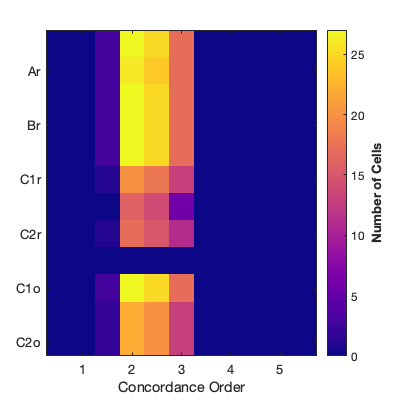


% Supplementary
fig3 = figure(3);
clf
set(fig3,'Position',[0, 200, 400, 400])
imagesc(unique)
%plot(unique')
%surf(unique)
%colormap(figureDetails.colorMap)
colormap(gca, plasma())
%xlim([0 7])
%ylim([0 nAlgos+1])
%plot(unique)
% title('Uniquely Identified Time Cells', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
xticklabels({'1', '2', '3', '4', '5', '6', '7', '8', '9', '10', '11'})
%axis tight
xlabel('Concordance Order', ...
    'FontSize', figureDetails.fontSize)
% ylabel('Algorithm', ...
%     'FontSize', figureDetails.fontSize)
yticklabels({'A-Boot', 'B-Boot', 'C1-Boot', 'C2-Boot', 'C1-Otsu', 'C2-Otsu', 'D-Otsu', 'E-Otsu', 'F1-Boot', 'F2-Boot', 'F1-Otsu', 'F2-Otsu'})
z = colorbar;
ylabel(z, 'Number of Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca, 'FontSize', figureDetails.fontSize)
print(['/Users/ananth/Desktop/' ...
    'Figure4sup_synthData_' ...
    mouseName '_' num2str(recordingDate)], ...
    '-djpeg')

## Save

% if ops0.saveData == 1
%     cData.methodA = mAOutput;
%     cData.methodB = mBOutput;
%     cData.methodC = mCOutput;
%     cData.methodD = mDOutput;
%     cData.methodE = mEOutput;
%     cData.methodF = mFOutput;
%     
%     save([saveFolder ...
%         db.mouseName '_comparativeSynthDataAnalysis_' ...
%         num2str(cDate) '_cRun' num2str(cRun) '_cData.mat'], ...
%         'cData')
% end
toc

Elapsed time is 516.853933 seconds.


disp('All done!')

All done!
